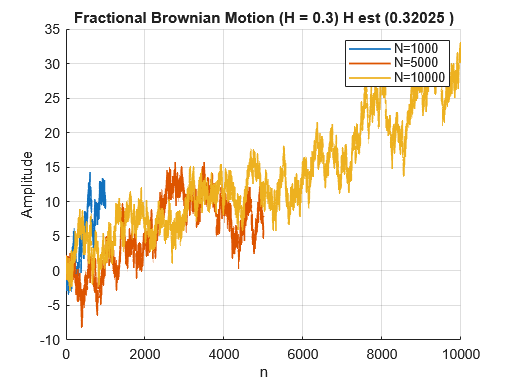

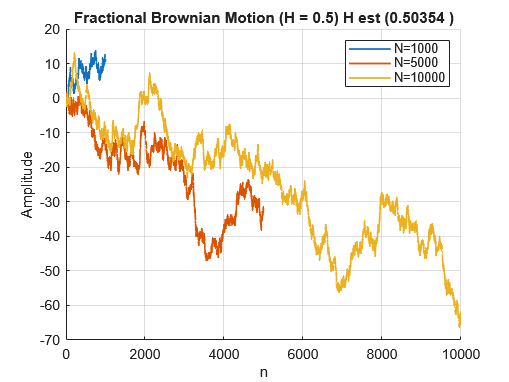

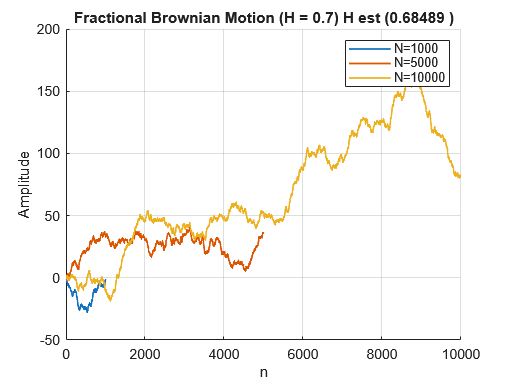

clear; close all; clc;
warning('off','MATLAB:plot:IgnoreImaginaryXYPart')

%% ---------------------------------------------------------
% PARAMETERS
% ---------------------------------------------------------
Hvals = [0.3, 0.5, 0.7];
Nvals = [1000, 5000, 10000];
numH  = numel(Hvals);
numN  = numel(Nvals);

colorsN = lines(numN);

%% ---------------------------------------------------------
% STORAGE
% ---------------------------------------------------------
fbm        = cell(numH, numN);
structfunc = cell(numH, numN);
Sqa        = cell(numH, numN);
Dqa        = cell(numH, numN);
C1         = cell(numH, numN);
C2         = cell(numH, numN);
C3         = cell(numH, numN);
logscales  = cell(numH, numN);
hexp       = cell(numH, numN);
tauq       = cell(numH, numN);

% NEW STORAGE FOR ALPHA AND F(ALPHA)
alpha_q    = cell(numH, numN);
f_alpha    = cell(numH, numN);

%% ---------------------------------------------------------
% MAIN LOOP — WTMM GLOBAL ANALYSIS
% ---------------------------------------------------------
for hi = 1:numH
    for ni = 1:numN

        H = Hvals(hi);
        N = Nvals(ni);

        % Generate fractional Brownian motion
        fbm{hi,ni} = wfbm(H, N);

        % WTMM global analysis
        [hexp{hi,ni}, tauq{hi,ni}, structfunc{hi,ni}] = wtmm(fbm{hi,ni});

        % Extract structure function components
        Tq        = structfunc{hi,ni}.Tq;        % Ns × 44
        loga      = structfunc{hi,ni}.logscales; % Ns × 1

        % Structure functions S(q,a) for q = -2:0.1:2
        Sqa{hi,ni} = Tq(:,1:41);

        % Dq
        %Dqa{hi,ni} = Tq(:,42:82);

        % Cumulants C1, C2, C3
        C1{hi,ni} = Tq(:,42);
        C2{hi,ni} = Tq(:,43);
        C3{hi,ni} = Tq(:,44);

        logscales{hi,ni} = loga;

        %% ---------------------------------------------------------
        % NEW: COMPUTE α(q) AND f(α)
        %% ---------------------------------------------------------
        q_axis = linspace(-2, 2, 41);   % same q as WTMM

        tau = tauq{hi,ni};

        % α(q) = dτ/dq
        alpha_q{hi,ni} = gradient(tau, q_axis);

        % f(α) = q α - τ(q)
        f_alpha{hi,ni} = q_axis .* alpha_q{hi,ni} - tau;

    end
end

%% ---------------------------------------------------------
% 1. SHOW THE NOISE (FBM)
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;
    for ni = 1:numN
        plot(fbm{hi,ni}, 'Color', colorsN(ni,:), 'LineWidth', 1.2)
    end
    title("Fractional Brownian Motion (H = " + string(Hvals(hi)) + ") H est (" + string(hexp{hi,ni})+" )")
    xlabel("n"); ylabel("Amplitude")
    legend("N="+string(Nvals))
    grid on
end

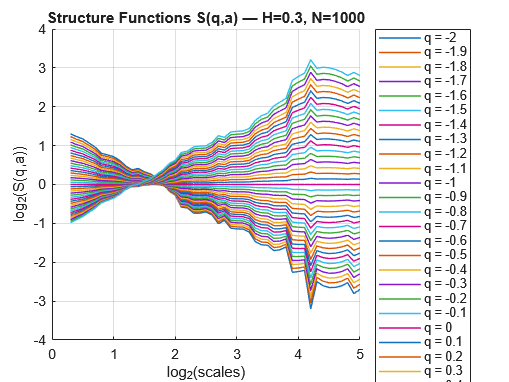

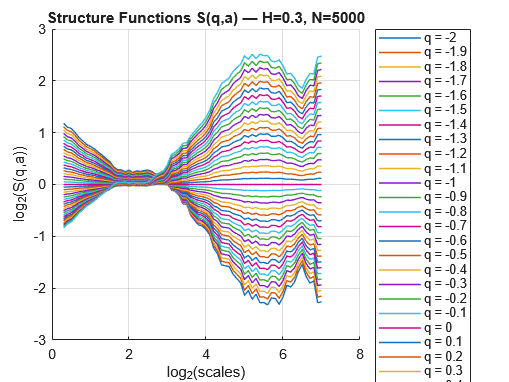

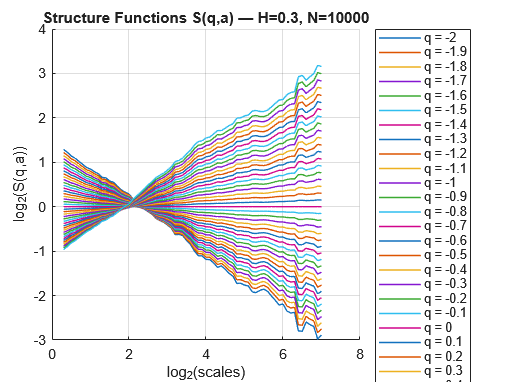

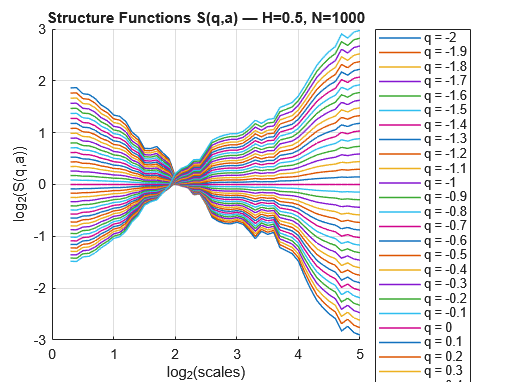

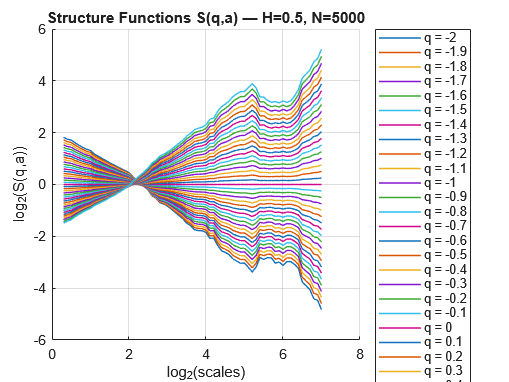

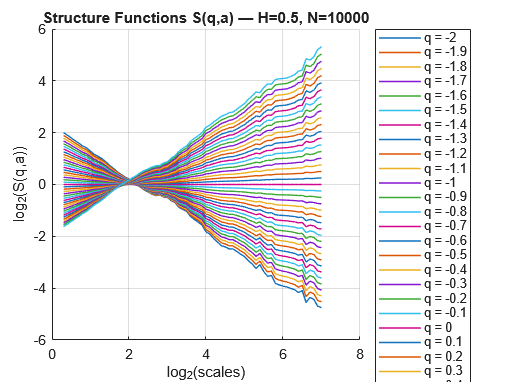

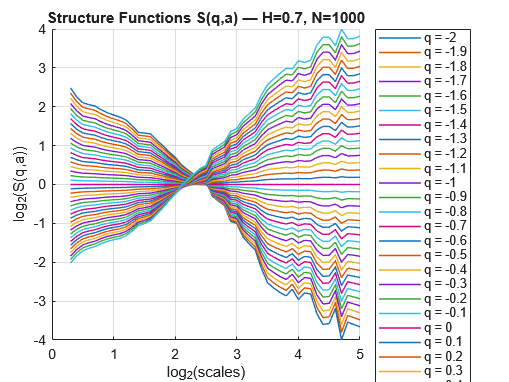

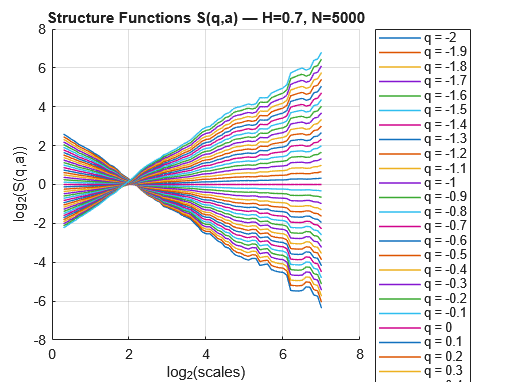


%% ---------------------------------------------------------
% 2. SHOW STRUCTURE FUNCTIONS S(q,a)
% ---------------------------------------------------------
q_axis = linspace(-2, 2, 41);

for hi = 1:numH
    for ni = 1:numN

        S = Sqa{hi,ni};
        loga = structfunc{hi,ni}.logscales;

        figure; hold on;
        plot(loga, S(:,:), 'LineWidth', 1.0)

        legend("q = " + string(round(q_axis, 3)), "Location", "bestoutside")
        xlabel("log_2(scales)")
        ylabel("log_2(S(q,a))")
        title("Structure Functions S(q,a) — H="+string(Hvals(hi))+", N="+string(Nvals(ni)))
        grid on
    end
end

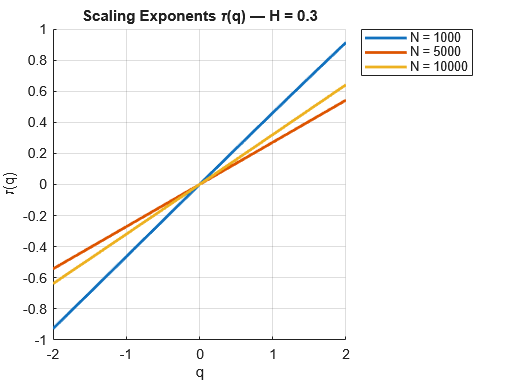

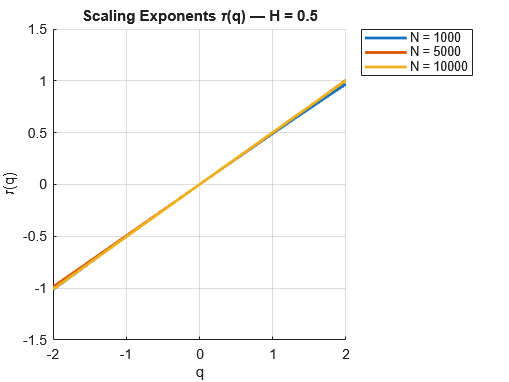

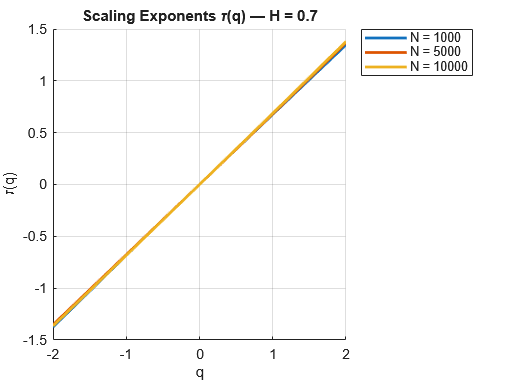


%% ---------------------------------------------------------
% 3. SHOW CUMULANTS C1, C2, C3
% ---------------------------------------------------------
% for hi = 1:numH
%     for ni = 1:numN
%         figure; hold on;
% 
%         plot(logscales{hi,ni}, C1{hi,ni}, 'LineWidth', 2, 'Color', colorsN(ni,:))
%         plot(logscales{hi,ni}, C2{hi,ni}, '--', 'LineWidth', 2, 'Color', colorsN(ni,:))
%         plot(logscales{hi,ni}, C3{hi,ni}, ':', 'LineWidth', 2, 'Color', colorsN(ni,:))
% 
%         xlabel("log_2(scale a)")
%         ylabel("Cumulant value")
%         title("WTMM Cumulants — H="+string(Hvals(hi))+", N="+string(Nvals(ni)))
%         legend("C1","C2","C3")
%         grid on
%     end
% end

%% ---------------------------------------------------------
% 6. PLOT τ(q) FOR ALL Nvals (separate figure)
% ---------------------------------------------------------
q_axis = linspace(-2, 2, 41);

for hi = 1:numH
    figure; hold on;

    for ni = 1:numN
        tau = tauq{hi,ni};

        plot(q_axis, tau, 'LineWidth', 2, ...
            'Color', colorsN(ni,:), ...
            'DisplayName', "N = " + string(Nvals(ni)));
    end

    xlabel("q");
    ylabel("\tau(q)");
    title("Scaling Exponents \tau(q) — H = " + string(Hvals(hi)));
    legend("Location","bestoutside");
    grid on;
end

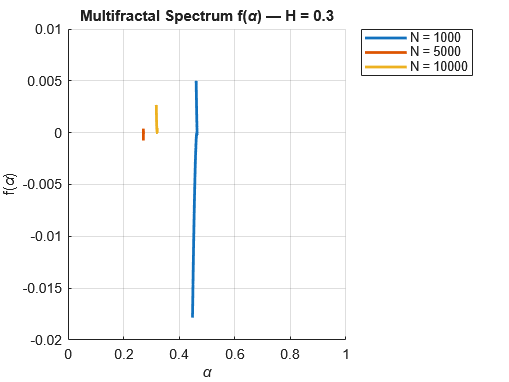

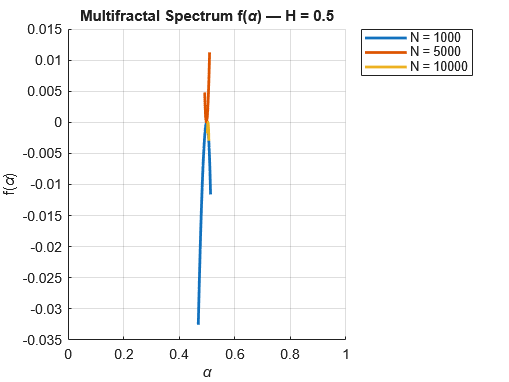

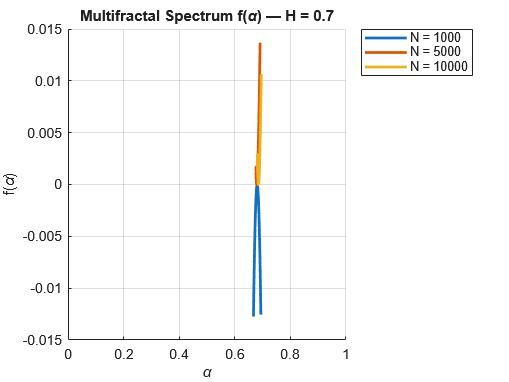



%% ---------------------------------------------------------
% 7. PLOT f(α) FOR ALL Nvals (separate figure)
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;

    for ni = 1:numN
        a_q = alpha_q{hi,ni};
        f_a = f_alpha{hi,ni};

        plot(a_q, f_a, 'LineWidth', 2, ...
            'Color', colorsN(ni,:), ...
            'DisplayName', "N = " + string(Nvals(ni)));
    end

    xlabel("\alpha");
    ylabel("f(\alpha)");
    title("Multifractal Spectrum f(\alpha) — H = " + string(Hvals(hi)));
    legend("Location","bestoutside");
    xlim([0 1])

    grid on;
end